# Reserve Variance Live Script 1

## Load Data

if ~exist("workspaceVarReserveVariance", 'var')
    load matlabReserveVariance.mat
    setInterpLatex()
end

## Save Data

 if exist("workspaceVarReserveVariance", 'var')
     clearVarsArray = clearVars();
     clear(clearVarsArray{:})
     clear clearVarsArray
     save matlabReserveVariance.mat
 end

% set the default intepreter to latex
setInterpLatex()

## Contents

Verifying Chapter 3 Work

## Assumptions / Notes

% note that this work follows on directly from my honours project

% maybe at some point I should be changing the workspace name to avoid
% confusion

## Verifying Chapter 3 Work

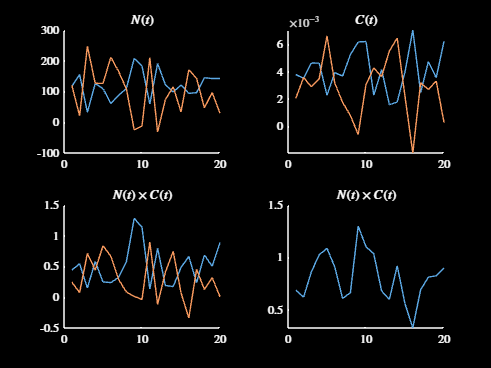

% because I'm now paranoid, let's make sure that the work I presented in
% chapter 3 actually makes sense - that is, that my variance calculation is
% correct
n1Hat = 100;
n2Hat = 130;
n1Std = 30;
n2Std = 50;
c1Hat = 0.004;
c2Hat = 0.003;
c1Std = 0.002;
c2Std = 0.0025;

% set the correlations
corrC = -0.9;
corrN = -0.9;

% run sim
figure
var1 = sim3ReefSystem(c1Hat, c2Hat, c1Std, c2Std, n1Hat, ...
    n2Hat, n1Std, n2Std, corrC, corrN);
darkFig()

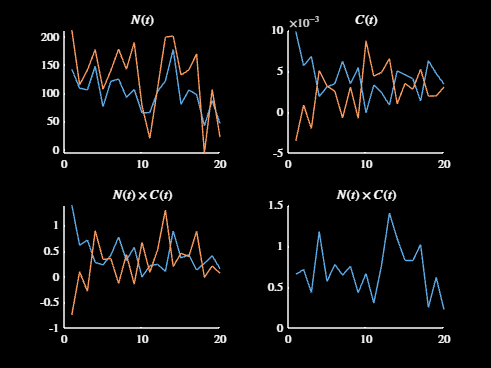


% run sim, but with one correlation larger
figure
var2 = sim3ReefSystem(c1Hat, c2Hat, c1Std, c2Std, n1Hat, ...
    n2Hat, n1Std, n2Std, corrC, 0.8);
darkFig()


var1

var1 = 0.0534

var2

var2 = 0.0934

% run the simulations on the system, and check that the variance of the
% system matches the variance I calculated (approximately), and using the
% cases that I showed in the other figure

% setup parameters for the simulation
nReps = 500;
simVar = cell(6, 1);
for i = 1:length(simVar)
    simVar{i} = zeros(1, nReps);
end
theorVar = zeros(6, 1);

% do a bunch of reps
for r = 1:nReps

    % case of both CVs below 1
    [simVar{1}(r), theorVar(1)] = sim3ReefSystem(0.007, 0.008, 0.003, ...
        0.002, 100, 120, 20, 30, -0.5, 0.5, "no");

    % do a case for both CVs equal to 1
    [simVar{2}(r), theorVar(2)] = sim3ReefSystem(0.007, 0.008, 0.007, ...
        0.008, 70, 80, 70, 80, 0.2, -0.9, "no");

    % do a case CVc > CVn
    [simVar{3}(r), theorVar(3)] = sim3ReefSystem(0.003, 0.002, 0.009, ...
        0.008, 80, 100, 100, 120, -0.34, 0.5, "no");

    % do a case CVc < CVn
    [simVar{4}(r), theorVar(4)] = sim3ReefSystem(0.003, 0.002, 0.001, ...
        0.005, 90, 80, 100, 120, -0.3, 0.8, "no");

    % do a case CVc > CVn but CVc == 1
    [simVar{5}(r), theorVar(5)] = sim3ReefSystem(0.003, 0.002, 0.003, ...
        0.002, 80, 100, 70, 80, 0.1, -0.6, "no");

    % do a case CVc < CVn but CVn == 1
    [simVar{6}(r), theorVar(6)] = sim3ReefSystem(0.003, 0.002, 0.001, ...
        0.0008, 90, 80, 90, 80, -0.5, -0.2, "no");

end

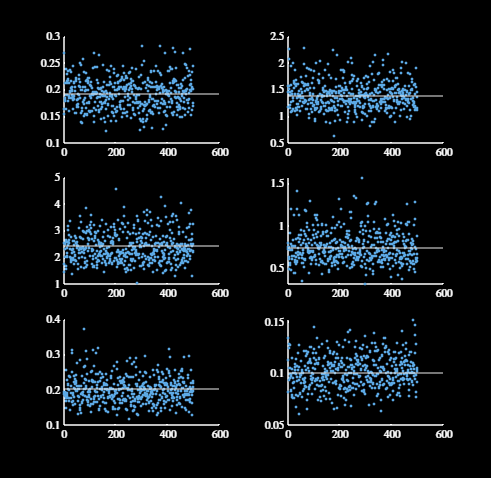

% plot the results
figure
tiledlayout(3, 2)
for i = 1:6
    nexttile
    hold on
    plot(simVar{i}, '.')
    yline(theorVar(i))
end
figResize(1.3)
darkFig()


% alright, that seems reasonable I trust my results now xd

% ok so I don't entirely trust my work, so let's then do the above one more
% time, for some slightly different parameters
% setup parameters for the simulation
nReps = 500;
simVar2 = cell(6, 1);
for i = 1:length(simVar2)
    simVar2{i} = zeros(1, nReps);
end
theorVar2 = zeros(6, 1);

% do a bunch of reps
for r = 1:nReps

    % case of both CVs below 1
    [simVar2{1}(r), theorVar2(1)] = sim3ReefSystem(0.008, 0.007, 0.002, ...
        0.003, 100, 120, 40, 10, 0.5, 0.5, "no");

    % do a case for both CVs equal to 1
    [simVar2{2}(r), theorVar2(2)] = sim3ReefSystem(0.003, 0.008, 0.003, ...
        0.008, 60, 90, 60, 90, -0.2, 0.4, "no");

    % do a case CVc > CVn
    [simVar2{3}(r), theorVar2(3)] = sim3ReefSystem(0.003, 0.002, 0.01, ...
        0.006, 80, 100, 100, 110, 0.25, -0.65, "no");

    % do a case CVc < CVn
    [simVar2{4}(r), theorVar2(4)] = sim3ReefSystem(0.003, 0.002, 0.001, ...
        0.005, 90, 80, 100, 120, 0.3, -0.2, "no");

    % do a case CVc > CVn but CVc == 1
    [simVar2{5}(r), theorVar2(5)] = sim3ReefSystem(0.005, 0.0025, 0.005, ...
        0.0025, 80, 100, 70, 80, -0.1, 0.45, "no");

    % do a case CVc < CVn but CVn == 1
    [simVar2{6}(r), theorVar2(6)] = sim3ReefSystem(0.003, 0.002, 0.001, ...
        0.0008, 100, 75, 100, 75, 0.5, 0.2, "no");

end

% note - the cv cases in the last two don't match the cases I was looking
% at in my honours but it's fine anyway whatever man

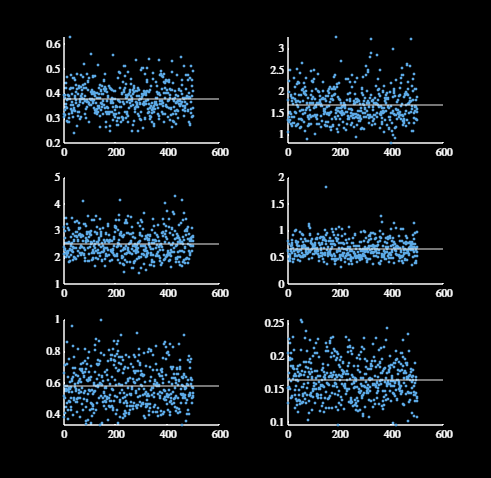

% plot the results
figure
tiledlayout(3, 2)
for i = 1:6
    nexttile
    hold on
    plot(simVar2{i}, '.')
    yline(theorVar2(i))
end
figResize(1.3)
darkFig()

% ok, so I now trust the variance calculation, but I also want to check the
% correlations hypothesis for some of the above examples

% let's do a plot where the dots from the non-optimal version are something
% and the other is something else idfk

nReps = 500;
simVar3 = cell(6, 3);
for i = 1:length(simVar3)
    for j = 1:3
        simVar3{i, j} = zeros(1, nReps);
    end
end
theorVar3 = zeros(6, 3);
strVec = strings(1, 6);

% do a bunch of reps
for r = 1:nReps

    % case of both CVs below 1
    strVec(1) = "$CV_C < 1$, $CV_N < 1$";
    [simVar3{1, 1}(r), theorVar3(1, 1)] = sim3ReefSystem(0.008, 0.007, ...
        0.002, 0.003, 100, 120, 40, 10, -0.8, -0.8, "no");
    [simVar3{1, 2}(r), theorVar3(1, 2)] = sim3ReefSystem(0.008, 0.007, ...
        0.002, 0.003, 100, 120, 40, 10, 0.5, -0.8, "no");
    [simVar3{1, 3}(r), theorVar3(1, 3)] = sim3ReefSystem(0.008, 0.007, ...
        0.002, 0.003, 100, 120, 40, 10, -0.8, 0.5, "no");

    % do a case for both CVs equal to 1
    strVec(2) = "$CV_C = CV_N = 1$";
    [simVar3{2, 1}(r), theorVar3(2, 1)] = sim3ReefSystem(0.003, 0.008, ...
        0.003, 0.008, 60, 90, 60, 90, -1, -0.7, "no");
    [simVar3{2, 2}(r), theorVar3(2, 2)] = sim3ReefSystem(0.003, 0.008, ...
        0.003, 0.008, 60, 90, 60, 90, 0.6, -1, "no");
    [simVar3{2, 3}(r), theorVar3(2, 3)] = sim3ReefSystem(0.003, 0.008, ...
        0.003, 0.008, 60, 90, 60, 90, -1, 0.7, "no");

    % do a case CVc > CVn
    strVec(3) = "$CV_C > CV_N$, $CV_C > 1$";
    [simVar3{3, 1}(r), theorVar3(3, 1)] = sim3ReefSystem(0.003, 0.002, ...
        0.01, 0.006, 80, 100, 100, 110, -0.75, -0.65, "no");
    [simVar3{3, 2}(r), theorVar3(3, 2)] = sim3ReefSystem(0.003, 0.002, ...
        0.01, 0.006, 80, 100, 100, 110, 0.75, -0.65, "no");
    [simVar3{3, 3}(r), theorVar3(3, 3)] = sim3ReefSystem(0.003, 0.002, ...
        0.01, 0.006, 80, 100, 100, 110, -0.75, 0.65, "no");

    % do a case CVc < CVn
    strVec(4) = "$CV_C < CV_N$, $CV_N > 1$";
    [simVar3{4, 1}(r), theorVar3(4, 1)] = sim3ReefSystem(0.003, 0.002, ...
        0.001, 0.0025, 90, 80, 150, 180, -0.6, -0.7, "no");
    [simVar3{4, 2}(r), theorVar3(4, 2)] = sim3ReefSystem(0.003, 0.002, ...
        0.001, 0.0025, 90, 80, 150, 180, 0.6, -0.6, "no");
    [simVar3{4, 3}(r), theorVar3(4, 3)] = sim3ReefSystem(0.003, 0.002, ...
        0.001, 0.0025, 90, 80, 150, 180, -0.6, 0.7, "no");

    % do a case CVc > CVn but CVc == 1
    strVec(5) = "$CV_C > CV_N$, $CV_C = 1$";
    [simVar3{5, 1}(r), theorVar3(5, 1)] = sim3ReefSystem(0.005, 0.0025, ...
        0.005, 0.0025, 80, 100, 70, 80, -1, -0.6, "no");
    [simVar3{5, 2}(r), theorVar3(5, 2)] = sim3ReefSystem(0.005, 0.0025, ...
        0.005, 0.0025, 80, 100, 70, 80, 0.5, -1, "no");
    [simVar3{5, 3}(r), theorVar3(5, 3)] = sim3ReefSystem(0.005, 0.0025, ...
        0.005, 0.0025, 80, 100, 70, 80, -1, 0.45, "no");

    % do a case CVc < CVn but CVn == 1
    strVec(6) = "$CV_C < CV_N$, $CV_N = 1$";
    [simVar3{6, 1}(r), theorVar3(6, 1)] = sim3ReefSystem(0.003, 0.002, ...
        0.001, 0.0008, 100, 75, 100, 75, -0.6, -1, "no");
    [simVar3{6, 2}(r), theorVar3(6, 2)] = sim3ReefSystem(0.003, 0.002, ...
        0.001, 0.0008, 100, 75, 100, 75, 0.5, -1, "no");
    [simVar3{6, 3}(r), theorVar3(6, 3)] = sim3ReefSystem(0.003, 0.002, ...
        0.001, 0.0008, 100, 75, 100, 75, -1, 0.2, "no");

end

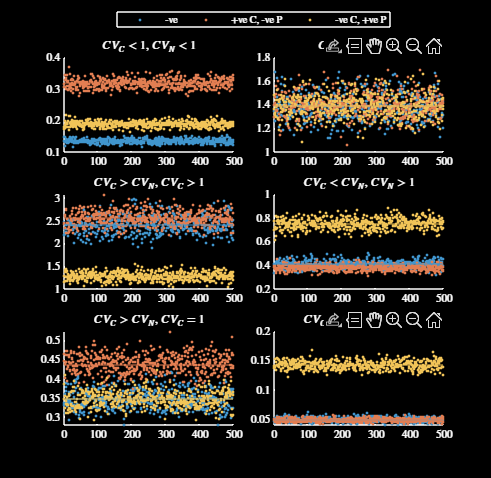

figure
tiledlayout(3, 2, 'TileSpacing', 'compact')
for i = 1:6
    nexttile
    hold on
    for j = 1:3
        plot(simVar3{i, j}, '.', 'Color', getColour(j))
        yline(theorVar3(i, j), 'Color', getColour(j))
    end
    xlim([0, 500])
    subtitle(strVec(i))
end
lG = legend('-ve', '', '+ve C, -ve P', '', '-ve C, +ve P', 'Orientation', ...
    'horizontal');
lG.Layout.Tile = 'north';
figResize(1.3)
darkFig()


% first is ok, second is fine, third is definitely fine, fourth is
% ok, fifth is ok, sixth is ok

% note, I think my shit is fucked - need to look back into my maths for the
% one where both of the CVs is 1 - shouldn't be able to just choose any
% correlations - I think that one should be -1, then the other is free to
% move around - yep, I think that's the case

% ok thank fuck, that is good news that all my shit works out xd

## Investigating the Optimal Positive Correlation

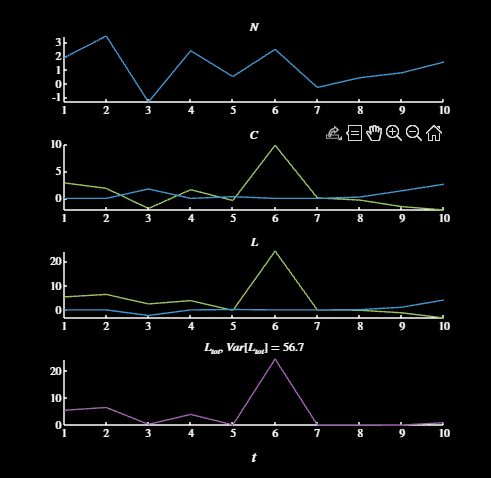

% ok so will need to look back through my notes, but it might not be a bad
% idae 
cvC = 3;
cvN = 1.3;
rhoN = 1;
rhoC = -1;
tMax = 10;
sim3Reefs(cvC, cvN, rhoC, rhoN, tMax, "plot");
darkFig()

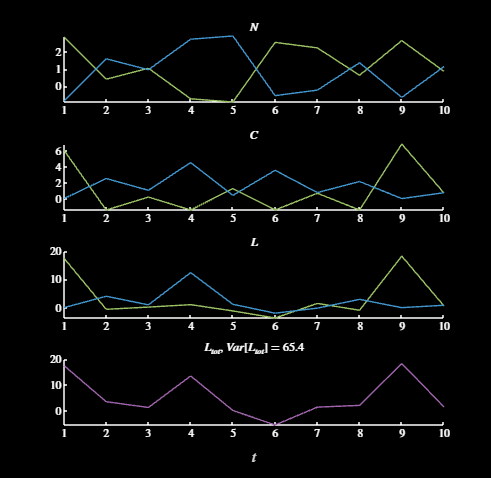


% do one where both correlations are negative
rhoN = -1;
sim3Reefs(cvC, cvN, rhoC, rhoN, tMax, "plot");
darkFig()

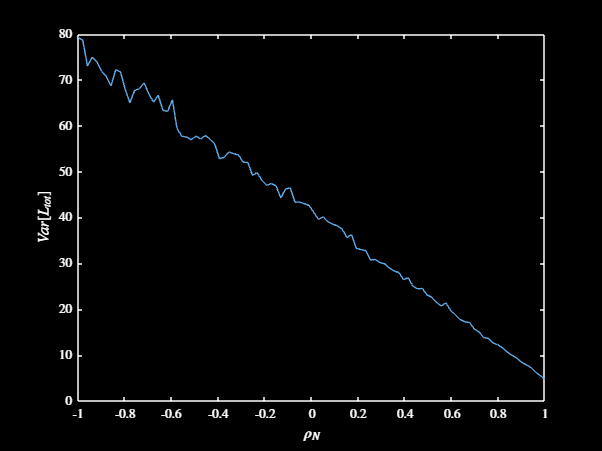

% loop over some shit and record the variance in larvae
cvC = 4;
cvN = 1.1;
rhoC = -1;
corrVec = linspace(-1, 1, 100);
varVec = zeros(1, length(corrVec));
nReps = 100;
tMax = 100;
for c = 1:length(corrVec)

    % loop over the number of repetitions
    for r = 1:nReps
        [~, ~, larvaeMat] = sim3Reefs(cvC, cvN, rhoC, corrVec(c), ...
            tMax);
        varVec(c) = varVec(c) + var(sum(larvaeMat, 2));
    end

    % average the variance
    varVec(c) = varVec(c) / nReps;

end

% let's look at the results
figure
plot(corrVec, varVec)
xlabel("$\rho_N$")
ylabel("$Var[L_{tot}]$")
darkFig()


% note - the above fucks it if you just do the variance thingy, then chop
% off the zeros - needs to be later expanded again in order to keep the
% variances actually reasonable

% let's do this shit a bunch of times and look into the results

% I'm a dumb cunt so let's check how my understanding of things is 
var8 = 4;
var1 = normrnd(1, var8, [1, 1000]);
var2 = std(var1)

var2 = 4.1085

var7 = std(var1);
var1(var1 < 0) = 0;
var2 = std(var1)

var2 = 2.6474

var3 = mean(var1)

var3 = 2.1813

var1 = var1 - mean(var1);
var1 = var1 / std(var1);
var2 = std(var1)

var2 = 1.0000

var3 = mean(var1)

var3 = -2.3803e-16

var1 = var1 * var7;
var2 = std(var1)

var2 = 4.1085

var3 = mean(var1)

var3 = -7.2475e-16

min(var1)

ans = -3.3850



% this shit it fucking stupid, I fucking hate this goddamn mf

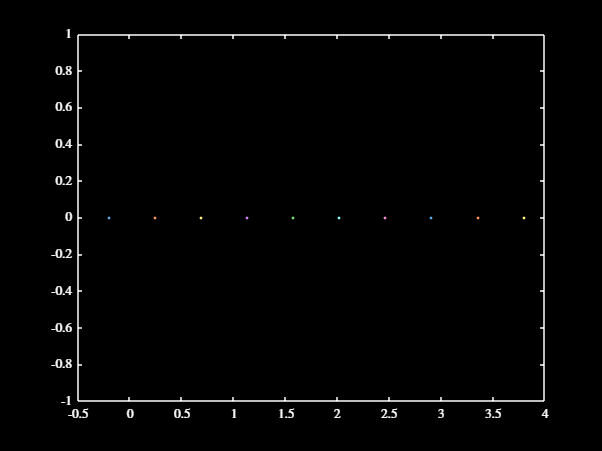

% fuck it we ball
var1 = linspace(0, 2, 10) - 0.1;
var1 = var1 * 2;
figure
plot(var1, 0, '.')
darkFig()


% fuck it we don't ball I give up for now, let's just see if I can
% understand this in some way anyway

% ok I don't know what bullshit I was doing above, but I have a new fun
% idea that I'm going to look into
popVec = [100, 200, 300];
connVec = [0.001, 0.002, 0.003];

% make a guideVec, this makes sense in my head but I can't put it into
% words
guideVec = [1, 1; 3, 3; 2, 2; 1, 3; 3, 1];

% ok, this is fucking perhaps a little batshit but bear? bare? with me
larvOutMat = zeros(length(guideVec), length(guideVec));
for p = 1:length(guideVec)
    for c = 1:length(guideVec)
        larvOutMat(p, c) = popVec(guideVec(p, 1)) * connVec(guideVec(c, 1)) ...
            + popVec(guideVec(p, 2)) * connVec(guideVec(c, 2));
    end
end

% plot this fucker
figure
imagesc(larvOutMat)
colormap(myColourMap())
colorbar()
xticks(1:5)
xtickVec = ["$C_1 \downarrow$, $C_2 \downarrow$", ...
    "$C_1 \uparrow$ , $C_2 \uparrow$", "$C_1$ --, $C_2$ --", ...
    "$C_1 \downarrow$, $C_2 \uparrow$", ...
    "$C_1 \uparrow$, $C_2 \downarrow$"];
xticklabels(xtickVec)
yticks(1:5)
ytickVec = ["$P_1 \downarrow$, $P_2 \downarrow$", ...
    "$P_1 \uparrow$ , $P_2 \uparrow$", "$P_1$ --, $P_2$ --", ...
    "$P_1 \downarrow$, $P_2 \uparrow$", ...
    "$P_1 \uparrow$, $P_2 \downarrow$"]

ytickVec = 1×5 string array
    "$P_1 \downarrow$, $P_2 \downarrow$"    "$P_1 \uparrow$ , $P_2 \uparrow$"    "$P_1$ --, $P_2$ --"    "$P_1 \downarrow$, $P_2 \uparrow$"    "$P_1 \uparrow$, $P_2 \downarrow$"


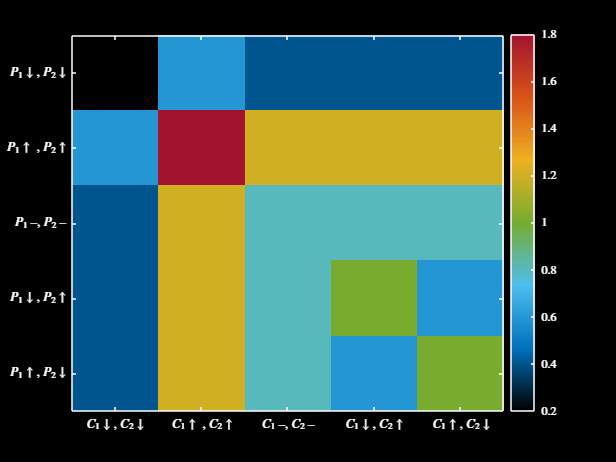

yticklabels(ytickVec)
darkFig()

% let's calc the sds, so we can find some scenarios for correct CV values
% first, for both with CV < 1
popCell{1} = [20, 100, 180];
connCell{1} = [0.002, 0.01, 0.018];
probVec = [1/3, 1/3, 1/3];
sdFunc = @(x, p) sqrt((x - mean(x)).^2 * p');
sdFunc(popVec, probVec)

ans = 65.3197

sdFunc(connVec, probVec)

ans = 0.0233


% CVn > CVc
popCell{2} = [1, 10, 1000];
connCell{2} = [0.002, 0.01, 0.018];
probVec = [1/3, 1/3, 1/3];
sdFunc = @(x, p) sqrt((x - mean(x)).^2 * p');
mean(popVec)

ans = 100

sdFunc(popVec, probVec)

ans = 65.3197


% CVc > CVn
popCell{3} = [20, 100, 180];
connCell{3} = [0, 0.001, 0.05];
probVec = [1/3, 1/3, 1/3];
sdFunc = @(x, p) sqrt((x - mean(x)).^2 * p');
mean(connVec)

ans = 0.0170

sdFunc(connVec, probVec)

ans = 0.0233

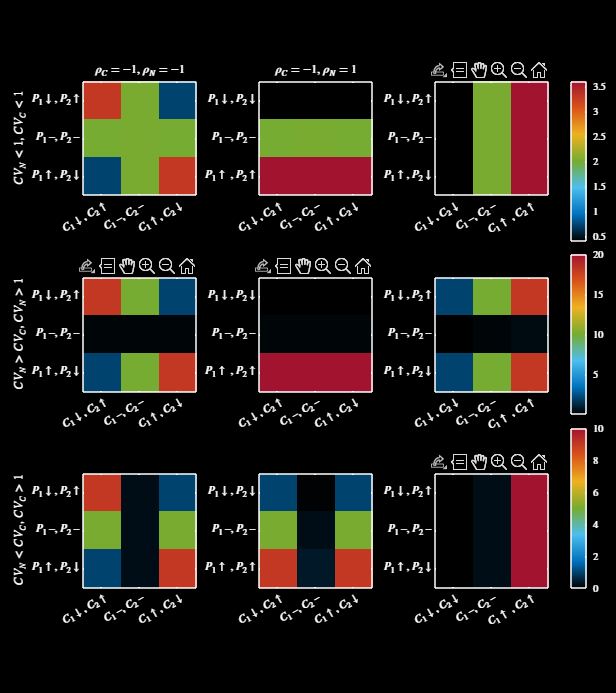

% ok, let's plot them on a strategy by strategy basis, for three different
% cases - both CVs < 1, and then CVc > CVn, and CVn > CVc
figure
tiledlayout(3, 3, "TileSpacing", "compact")

% setup some shit
var3 = ["$CV_N < 1$, $CV_C < 1$", "$CV_N > CV_C$, $CV_N > 1$", ...
    "$CV_N < CV_C$, $CV_C > 1$"];
guideVec = [1, 1; 3, 3; 2, 2; 1, 3; 3, 1];
rowIndCell = {[4, 3, 5], [1, 3, 2], [4, 3, 5]};
colIndCell = {[4, 3, 5], [4, 3, 5], [1, 3, 2]};
subtitleVec = ["$\rho_C = -1$, $\rho_N = -1$", "$\rho_C = -1$, $\rho_N = 1$", ...
    "$\rho_C = 1$, $\rho_N = -1$"];
ylabelVec = ["$CV_N < 1$, $CV_C < 1$", "$CV_N > CV_C$, $CV_N > 1$", ...
    "$CV_N < CV_C$, $CV_C > 1$"];

for i = 1:3

    % form the larvOutMat ok I don't know what bullshit I was doing above,
    % but I have a new fun idea that I'm going to look into
    popVec = popCell{i};
    connVec = connCell{i};

    % ok, this is perhaps a little batshit but bear? bare? with me
    larvOutMat = zeros(length(guideVec), length(guideVec));
    for p = 1:length(guideVec)
        for c = 1:length(guideVec)
            larvOutMat(p, c) = popVec(guideVec(p, 1)) * connVec(guideVec(c, 1)) ...
                + popVec(guideVec(p, 2)) * connVec(guideVec(c, 2));
        end
    end

    % plot the cases using a for loop
    clear var1
    for j = 1:3
    
        % plot shit
        var1(j) = nexttile;
        imagesc(larvOutMat(rowIndCell{j}, colIndCell{j}))
        colormap(myColourMap())
        xticks(1:3)
        xticklabels(xtickVec(colIndCell{j}))
        yticks(1:3)
        yticklabels(ytickVec(rowIndCell{j}))
        if i == 1
            subtitle(subtitleVec(j))
        end
        if j == 1
            ylabel(ylabelVec(i))
        end
        axis square

    end

    % make it look ok
    set(var1, 'Colormap', myColourMap())
    climits = cell2mat(get(var1, 'clim'));
    cmin = min(climits(:,1));
    cmax = max(climits(:,2));
    set(var1, 'clim', [cmin cmax]);
    var2 = colorbar();
    var2.Layout.Tile = "east";

end

figResize(1.5)
darkFig()

% let's redo the above, but this time I'm gonna adjust the colours for
% probabilities, so that I can attempt to make the differences between
% cases appear more significant
% first, for both with CV < 1
popCell{1} = [20, 100, 180];
connCell{1} = [0.002, 0.01, 0.018];
probPopCell{1} = [1/3, 1/3, 1/3];
probConnCell{1} = [1/3, 1/3, 1/3];
sdFunc(popVec, probVec)

ans = 65.3197

sdFunc(connVec, probVec)

ans = 0.0351


% CVn > CVc
popCell{2} = [1, 10, 1000];
connCell{2} = [0.008, 0.01, 0.012];
probPopCell{2} = [1/6, 2/3, 1/6];
probConnCell{2} = [1/3, 1/3, 1/3];
popCell{2} * probPopCell{2}'

ans = 173.5000

sdFunc(popCell{2}, probPopCell{2})

ans = 404.1825


% CVc > CVn
popCell{3} = [50, 100, 150];
connCell{3} = [0, 0.001, 0.075];
probPopCell{3} = [1/3, 1/3, 1/3];
probConnCell{3} = [1/6, 2/3, 1/6];
connCell{3} * probConnCell{3}'

ans = 0.0132

sdFunc(connCell{3}, probConnCell{3})

ans = 0.0302

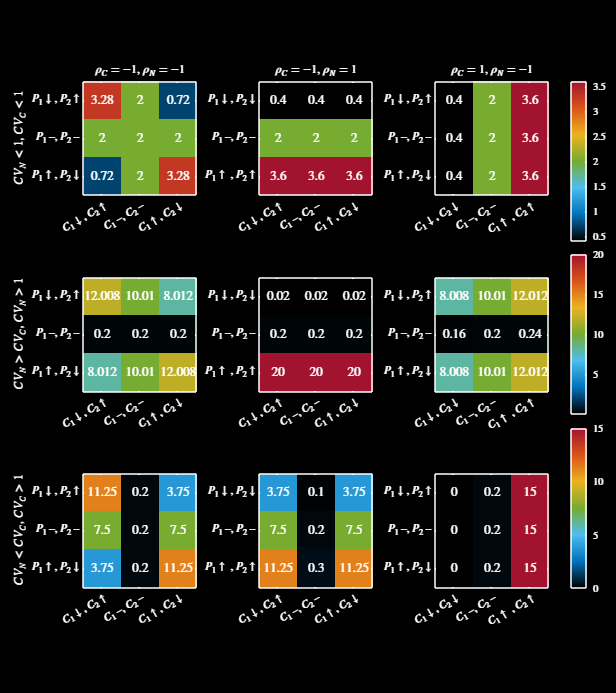

% let's do another plot like this, but now we're gonna overlay it with the
% probabilities, and then calculate the sum

% ok, let's plot them on a strategy by strategy basis, for three different
% cases - both CVs < 1, and then CVc > CVn, and CVn > CVc
figure
tiledlayout(3, 3, "TileSpacing", "compact")

% fuck wait - I'm not sure if scaling these by probabilities makes sense in
% this manner - I'm pretty sure that this math is wrong and so doesn't make
% sense - yep no it definitely doesn't

% setup some shit
var3 = ["$CV_N < 1$, $CV_C < 1$", "$CV_N > CV_C$, $CV_N > 1$", ...
    "$CV_N < CV_C$, $CV_C > 1$"];
guideVec = [1, 1; 3, 3; 2, 2; 1, 3; 3, 1];
rowIndCell = {[4, 3, 5], [1, 3, 2], [4, 3, 5]};
colIndCell = {[4, 3, 5], [4, 3, 5], [1, 3, 2]};
subtitleVec = ["$\rho_C = -1$, $\rho_N = -1$", "$\rho_C = -1$, $\rho_N = 1$", ...
    "$\rho_C = 1$, $\rho_N = -1$"];
ylabelVec = ["$CV_N < 1$, $CV_C < 1$", "$CV_N > CV_C$, $CV_N > 1$", ...
    "$CV_N < CV_C$, $CV_C > 1$"];

for i = 1:3

    % form the larvOutMat ok I don't know what bullshit I was doing above,
    % but I have a new fun idea that I'm going to look into
    popVec = popCell{i};
    connVec = connCell{i};

    % ok, this is perhaps a little batshit but bear? bare? with me
    larvOutMat = zeros(length(guideVec), length(guideVec));
    for p = 1:length(guideVec)
        for c = 1:length(guideVec)
            larvOutMat(p, c) = popVec(guideVec(p, 1)) * connVec(guideVec(c, 1)) ...
                * probPopCell{i}(guideVec(p, 1)) ...
                * probConnCell{i}(guideVec(c, 1)) + popVec(guideVec(p, 2)) ...
                * connVec(guideVec(c, 2)) * probPopCell{i}(guideVec(p, 2)) ...
                * probConnCell{i}(guideVec(c, 2)); 
        end
    end

    % plot the cases using a for loop
    clear var1
    for j = 1:3
    
        % plot shit
        var1(j) = nexttile;
        imagescText(larvOutMat(rowIndCell{j}, colIndCell{j}))
        colormap(myColourMap())
        xticks(1:3)
        xticklabels(xtickVec(colIndCell{j}))
        yticks(1:3)
        yticklabels(ytickVec(rowIndCell{j}))
        if i == 1
            subtitle(subtitleVec(j))
        end
        if j == 1
            ylabel(ylabelVec(i))
        end
        axis square

    end

    % make it look ok
    set(var1, 'Colormap', myColourMap())
    climits = cell2mat(get(var1, 'clim'));
    cmin = min(climits(:,1));
    cmax = max(climits(:,2));
    set(var1, 'clim', [cmin cmax]);
    var2 = colorbar();
    var2.Layout.Tile = "east";

end

figResize(1.5)
darkFig()

% solving some shit because I'm too lazy to do it by hand again
syms a x p
var1 = solve(((x - a)^2 + (x + a)^2) / p == x, a)

$$var1 = \left(\begin{array}{c} -\frac{\sqrt{2}\,\sqrt{x\,\left(p-2\,x\right)}}{2}\\ \frac{\sqrt{2}\,\sqrt{x\,\left(p-2\,x\right)}}{2} \end{array}\right)$$

subs(var1, [x, p], [100, 6])

$$ans = \left(\begin{array}{c} -\frac{\sqrt{2}\,\sqrt{19400}\,\mathrm{i}}{2}\\ \frac{\sqrt{2}\,\sqrt{19400}\,\mathrm{i}}{2} \end{array}\right)$$

var1 = solve(((x - a)^2 + (x + a)^2) / p == x, p)

$$var1 = \frac{2\,a^{2}+2\,x^{2}}{x}$$

subs(var1, [x, a], [100, 10])

$$ans = 202$$


% hmmmmmmmm, maybe I'm not on to much with this one - whatever tho

% hnmmmmmm, wait maybe I still am

% fuck this is hard aye

## Functions

function [popMat, conHistMat, larvaeMat] = sim3Reefs(cvC, cvN, rhoC, ...
    rhoN, tMax, plotInd)
% just want to write a function here that I can re-use for simulating the
% simple 3 reef problem presented in my thesis

% both populations and connectivities are just being taken as
% non-dimensionalised values for ease of analysis

% for now I'm going to keep it simple, but later could change the cv values
% to be vectors

% maybe later could avoid plotting, but for now want to visualise the
% results

% inputs:

% cvC - the coefficient of variation-like statistic I mention in my
    % Honours, which is the multiple of the coefficients of variation for
    % the two reefs' connectivity variation
% cvN - same as the above, but for the population fluctuations
% rhoC - the correlation coefficient for the two reef's larval output
% rhoN - the correlation coefficient between the two populations
% tMax - the number of timesteps to simulate for
% plotInd - optional - specify as "plot" if the results are to be plotted -
    % default is "no"

% outputs:

% popMat - a matrix where popMat(t, i) is the population at timestep t of
    % the ith reef
% conHistMat - a matrix where conHistMat(t, i) is the connectivity value at
    % timestep t for reef i
% larvaeMat - a matrix where larvaeMat(t, i) is the quantity of larvae
    % produced at time t by reef i

% set a default for the plotInd
if nargin < 6 || isempty(plotInd)
    plotInd = "no";
end

% generate a set of populations, ensuring they are non-negative
muVec = [1, 1];
sigmaMat = [cvN^2, rhoN * cvN^2; rhoN * cvN^2, cvN^2];
popMat = mvnrnd(muVec, sigmaMat, tMax);

% ensure the values are all above 0
% popMat(popMat < 0) = 0;

% now generate a set of connectivities
sigmaMat = [cvC^2, rhoC * cvC^2; rhoC * cvC^2, cvC^2];
conHistMat = mvnrnd(muVec, sigmaMat, tMax);

% this is a bit batshit, but for things to work out I'll need to centre and
% normalise before expanding again
oldVar = var(conHistMat(:, 1));
conHistMat(conHistMat < 0) = 0;
conHistMat(:, 1) = conHistMat(:, 1) - mean(conHistMat(:, 1));
conHistMat(:, 1) = oldVar * (conHistMat(:, 1) ./ var(conHistMat(:, 1))) + 1;

% calculate the amount of larvae produced both for each year, and in total
larvaeMat = popMat .* conHistMat;
larvaeVec = sum(larvaeMat, 2);

if plotInd == "plot"

    % make some fun little plots
    figure
    tL = tiledlayout(4, 1, "TileSpacing", "compact");

    % plot the populations in the first box
    nexttile
    hold on
    plot(popMat(:, 1), "Color", getColour("g"))
    plot(popMat(:, 2), "Color", getColour("b"))
    title("$N$")

    % plot the connectivities in the next
    nexttile
    hold on
    plot(conHistMat(:, 1), "Color", getColour("g"))
    plot(conHistMat(:, 2), "Color", getColour("b"))
    title("$C$")

    % now plot the larvae
    nexttile
    hold on
    plot(larvaeMat(:, 1), "Color", getColour("g"))
    plot(larvaeMat(:, 2), "Color", getColour("b"))
    title("$L$")

    % now plot the sum of the larvae
    nexttile
    plot(larvaeVec, "Color", getColour("p"))
    title("$L_{tot}$, $Var[L_{tot}] = " + num2str(var(larvaeVec), ...
        3) + "$")
    box off

    % throw in some titles n shit
    xlabel(tL, "$t$", 'Interpreter', 'Latex')
    figResize(1.3)

end

end